# Condensed Plots: 

This script aims to find a mathematical relationship between the error of the Autolanding NN Output and the distance out-of-distribution from the training data at a certain state threshold. 

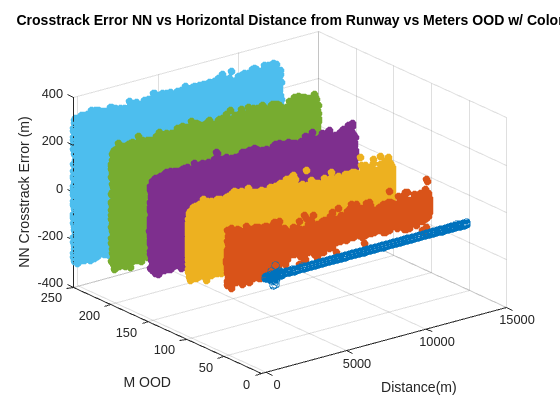

clear variables; close all; clc;
base_path = "/home/achadbo/XPlaneAutolandScenario";
err_path = base_path + "/errors";
plot_path = base_path + "/plots";
date = "/2024-4-23";
gen = "/generated_states.csv";
com = "/combined_states.csv";


%1: Gather all Relevant OOD data and set variables 

csvData50_g = readtable(err_path + "/2024-5-24/50/generated_states.csv"); %50m, OOD by 0
csvData50_c = readtable(plot_path + "/2024-5-24/50/combined_states.csv");

error_NN_h_50 = csvData50_c.error_h; %NN Error, height offset 
error_NN_y_50 = csvData50_c.error_y; %NN Error, crosstrack offset 
y_pred_50 = csvData50_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_50 = csvData50_g.h_err_NN; %NN Output- Predicted height offset
h_true_50 = csvData50_g.h_err_true; %True height error based on state info 

%True State Information 
x50 = csvData50_c.x; %Horizontal distance from runway 
h50 = csvData50_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData100_g = readtable(err_path + date + "/100" + gen);%100m, OOD by 50
csvData100_c = readtable(plot_path + date + "/100" + com);

error_NN_h_100 = csvData100_c.error_h; %NN Error, height offset 
error_NN_y_100 = csvData100_c.error_y; %NN Error, crosstrack offset 
y_pred_100 = csvData100_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_100 = csvData100_g.h_err_NN; %NN Output- Predicted height offset
h_true_100 = csvData100_g.h_err_true; %True height error based on state info 

%True State Information 
x100 = csvData100_c.x; %Horizontal distance from runway 
h100 = csvData100_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData150_g = readtable(err_path + date + "/150" + gen); %150m, OOD by 100
csvData150_c = readtable(plot_path + date + "/150" + com);

error_NN_h_150 = csvData150_c.error_h; %NN Error, height offset 
error_NN_y_150 = csvData150_c.error_y; %NN Error, crosstrack offset 
y_pred_150 = csvData150_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_150 = csvData150_g.h_err_NN; %NN Output- Predicted height offset
h_true_150 = csvData150_g.h_err_true; %True height error based on state info 

%True State Information 
x150 = csvData150_c.x; %Horizontal distance from runway 
h150 = csvData150_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData200_g = readtable(err_path + date + "/200" + gen); %200m, OOD by 150
csvData200_c = readtable(plot_path + date + "/200" + com);

error_NN_h_200 = csvData200_c.error_h; %NN Error, height offset 
error_NN_y_200 = csvData200_c.error_y; %NN Error, crosstrack offset 
y_pred_200 = csvData200_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_200 = csvData200_g.h_err_NN; %NN Output- Predicted height offset
h_true_200 = csvData200_g.h_err_true; %True height error based on state info 

%True State Information 
x200 = csvData200_c.x; %Horizontal distance from runway 
h200 = csvData200_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData250_g = readtable(err_path + date + "/250" + gen); %250m, OOD by 200
csvData250_c = readtable(plot_path + date + "/250" + com);

error_NN_h_250 = csvData250_c.error_h; %NN Error, height offset 
error_NN_y_250 = csvData250_c.error_y; %NN Error, crosstrack offset 
y_pred_250 = csvData250_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_250 = csvData250_g.h_err_NN; %NN Output- Predicted height offset
h_true_250 = csvData250_g.h_err_true; %True height error based on state info 

%True State Information 
x250 = csvData250_c.x; %Horizontal distance from runway 
h250 = csvData250_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData300_g = readtable(err_path + date + "/300" + gen); %300m, OOD by 250
csvData300_c = readtable(plot_path + date + "/300" + com);

error_NN_h_300 = csvData300_c.error_h; %NN Error, height offset 
error_NN_y_300 = csvData300_c.error_y; %NN Error, crosstrack offset 
y_pred_300 = csvData300_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_300 = csvData300_g.h_err_NN; %NN Output- Predicted height offset
h_true_300 = csvData300_g.h_err_true; %True height error based on state info 

%True State Information 
x300 = csvData300_c.x; %Horizontal distance from runway 
h300 = csvData300_c.h; %True Height (Altitude relative to runway) 

%=======================================================================
%=======================================================================

%2: Pinpoint the Graphs that we want to condense (Add photos of collected
%data from Notes to pdf) 
    %Most relevant graphs: 
        % Crosstrack Error NN vs Horizontal Distance from Runway 
        % Crosstrack Error NN vs True Height (Altitude relative to runway) 

        % Height Error NN vs Horizontal Distance from Runway 
        % Height Error NN vs True Height (Altitude relative to runway) 

    % Would be Interesting to explore (Not completed here) 
        % Crosstrack Error NN vs Predicted Crosstrack Offset (NN Output)
        % Height Error NN vs Predicted Height Offset (NN Output) 

%=======================================================================
%=======================================================================

%3: Create 3D scatter plots where x = distance, y = OOD and z = NN Error
%and condense 

%Fun Matrices: 
x = [x50; x100; x150; x200; x250; x300]; 
h = [h50; h100; h150; h200; h250; h300]; 
error_NN_h = [error_NN_h_50; error_NN_h_100; error_NN_h_150; error_NN_h_200; error_NN_h_250; error_NN_h_300];
error_NN_y = [error_NN_y_50; error_NN_y_100; error_NN_y_150; error_NN_y_200; error_NN_y_250; error_NN_y_300];
y_pred =  [y_pred_50; y_pred_100; y_pred_150; y_pred_200; y_pred_250; y_pred_300];
h_pred = [h_pred_50; h_pred_100; h_pred_150; h_pred_200; h_pred_250; h_pred_300];
h_true = [h_true_50; h_true_100; h_true_150; h_true_200; h_true_250; h_true_300];
zero = repelem(0, length(x50)); 
fifty = repelem(50, length(x100)); 
hundred = repelem(100, length(x150)); 
hundfif = repelem(150, length(x200)); 
twohun = repelem(200, length(x250)); 
twohunfif = repelem(250, length(x300)); 
ODD_m = [zero'; fifty'; hundred'; hundfif'; twohun'; twohunfif']; 

%Starting with the "most relevant"
%First we need to make a table for each plot (Doing this early in case it
%makes bounding easier)- it did not but I'll keep it in in case a blanket
%function is deemed appropriate 

% Crosstrack Error NN vs Horizontal Distance from Runway 
tab1 = table(x, ODD_m, error_NN_y);

% Crosstrack Error NN vs True Height (Altitude relative to runway) 
tab2 = table(h, ODD_m, error_NN_y);

% Height Error NN vs Horizontal Distance from Runway 
tab3 = table(x, ODD_m, error_NN_h);

% Height Error NN vs True Height (Altitude relative to runway) 
tab4 = table(h, ODD_m, error_NN_h);

%PLOTS + Condense 
%========================================================================================

%Initial Plot 
% scatter3(tab1.x, tab1.ODD_m, tab1.error_NN_y);
% %axis equal;
% title('Crosstrack Error NN vs Horizontal Distance from Runway vs Meters OOD');
% xlabel('Distance(m)');
% ylabel('M OOD');
% zlabel('NN Crosstrack Error (m)');

scatter3(x50, zero', error_NN_y_50);
hold on; 
scatter3(x100, fifty', error_NN_y_100,"filled");
scatter3(x150, hundred', error_NN_y_150,"filled");
scatter3(x200, hundfif', error_NN_y_200,"filled");
scatter3(x250, twohun', error_NN_y_250,	"filled");
scatter3(x300, twohunfif', error_NN_y_300,"filled");
title('Crosstrack Error NN vs Horizontal Distance from Runway vs Meters OOD w/ Color');
xlabel('Distance(m)');
ylabel('M OOD');
zlabel('NN Crosstrack Error (m)');
hold off; 


%Create Cutoff Threshold for data (3000 m seemed reasonable based on the
%behavior of the original graphs, but it can also be decreased or increased
%as needed) 

x50thresh = x50(x50 > 3000); 
x100thresh = x100(x100 > 3000); 
x150thresh = x150(x150 > 3000); 
x200thresh = x200(x200 > 3000); 
x250thresh = x250(x250 > 3000); 
x300thresh = x300(x300 > 3000); 

zerothresh = zero(x50 > 3000); 
fiftythresh = fifty(x100 > 3000); 
hundredthresh = hundred(x150 > 3000); 
hundfifthresh = hundfif(x200 > 3000); 
twohunthresh = twohun(x250 > 3000); 
twohunfifthresh = twohunfif(x300 > 3000); 

error_NN_y_50_t= error_NN_y_50(x50 > 3000); 
error_NN_y_100_t = error_NN_y_100(x100 > 3000); 
error_NN_y_150_t = error_NN_y_150(x150 > 3000); 
error_NN_y_200_t = error_NN_y_200(x200 > 3000); 
error_NN_y_250_t = error_NN_y_250(x250 > 3000); 
error_NN_y_300_t = error_NN_y_300(x300 > 3000); 

%Take the maxes of each error at x OOD- will be simpler mathematically than fitting a
%function to each and trying to build a new function off that 

max50 = max(max(error_NN_y_50_t), abs(min(error_NN_y_50_t)))

max50 = 8.1850

max100 = max(max(error_NN_y_100_t), abs(min(error_NN_y_100_t)))

max100 = 113.7762

max150 = max(max(error_NN_y_150_t), abs(min(error_NN_y_150_t)))

max150 = 178.4445

max200 = max(max(error_NN_y_200_t), abs(min(error_NN_y_200_t)))

max200 = 236.3171

max250 = max(max(error_NN_y_250_t), abs(min(error_NN_y_250_t)))

max250 = 281.1159

max300 = max(max(error_NN_y_300_t), abs(min(error_NN_y_300_t)))

max300 = 328.0184

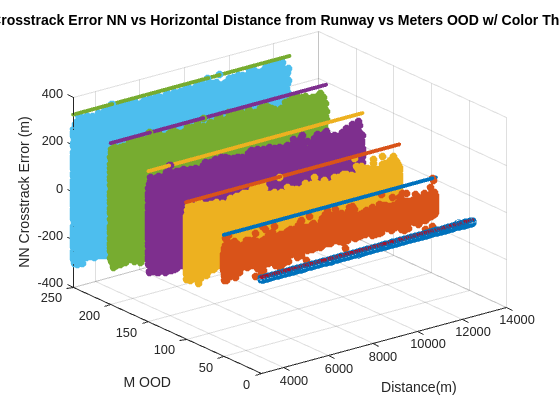


%New Plot- just to visualize cutoff and ensure reasonable 
scatter3(x50thresh, zerothresh', error_NN_y_50_t);
hold on; 
scatter3(x100thresh, fiftythresh', error_NN_y_100_t,"filled");
scatter3(x150thresh, hundredthresh', error_NN_y_150_t,"filled");
scatter3(x200thresh, hundfifthresh', error_NN_y_200_t,"filled");
scatter3(x250thresh, twohunthresh', error_NN_y_250_t,	"filled");
scatter3(x300thresh, twohunfifthresh', error_NN_y_300_t,"filled");
title('Crosstrack Error NN vs Horizontal Distance from Runway vs Meters OOD w/ Color Thresh');
xlabel('Distance(m)');
ylabel('M OOD');
zlabel('NN Crosstrack Error (m)');

plot3(x50thresh, zerothresh', repelem(max50, length(x50thresh)), 'LineWidth',3); 
plot3(x100thresh, fiftythresh', repelem(max100, length(x100thresh)), 'LineWidth',3); 
plot3(x150thresh, hundredthresh', repelem(max150, length(x150thresh)), 'LineWidth',3); 
plot3(x200thresh, hundfifthresh', repelem(max200, length(x200thresh)), 'LineWidth',3); 
plot3(x250thresh, twohunthresh', repelem(max250, length(x250thresh)), 'LineWidth',3); 
plot3(x300thresh, twohunfifthresh', repelem(max300, length(x300thresh)),'LineWidth',3); 
hold off; 


%Now: 2D function! Again just easier (for me) to visualize 
ood = [0, 50, 100, 150, 200, 250]; 
maxes = [max50, max100, max150, max200, max250, max300]; 
scatter(ood, maxes); 
title('Crosstrack Error NN Max vs Meters OOD @3000-14000m Dist');
xlabel('M OOD');
ylabel('NN Crosstrack Error Max (m)');

%Fit a function! (5th degree polynomial)
f = fit(ood', maxes', 'poly5');

f =      Linear model Poly5:
     f(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients:
       p1 =    1.65e-09
       p2 =  -1.094e-06
       p3 =   0.0002707
       p4 =    -0.03273
       p5 =       3.198
       p6 =       8.185

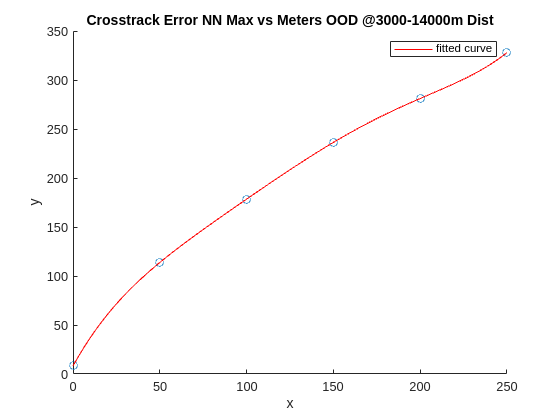

hold on; 
plot(f); 
hold off; 

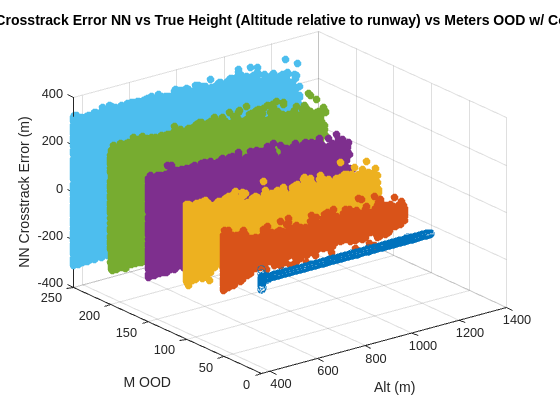


%The piecewise can then be written using the constants defined by the fit
%function- could also consider rounding the max values up to create better
%guarantee and write linear function, which may be easier from a
%computational standpoint 

%========================================================================================

% scatter3(tab2.h, tab2.ODD_m, tab2.error_NN_y);
% %axis equal;
% title('Crosstrack Error NN vs True Height (Altitude relative to runway) vs Meters OOD');
% xlabel('Alt (m)');
% ylabel('M OOD');
% zlabel('NN Crosstrack Error (m)');

scatter3(h50, zero', error_NN_y_50);
hold on; 
scatter3(h100, fifty', error_NN_y_100,"filled");
scatter3(h150, hundred', error_NN_y_150,"filled");
scatter3(h200, hundfif', error_NN_y_200,"filled");
scatter3(h250, twohun', error_NN_y_250,	"filled");
scatter3(h300, twohunfif', error_NN_y_300,"filled");
title('Crosstrack Error NN vs True Height (Altitude relative to runway) vs Meters OOD w/ Color');
xlabel('Alt (m)');
ylabel('M OOD');
zlabel('NN Crosstrack Error (m)');
hold off; 


%Create Cutoff Threshold for data (600 m seemed reasonable based on the
%behavior of the original graphs, but it can also be decreased or increased
%as needed) 

h50thresh = h50(h50 > 600); 
h100thresh = h100(h100 > 600); 
h150thresh = h150(h150 > 600); 
h200thresh = h200(h200 > 600); 
h250thresh = h250(h250 > 600); 
h300thresh = h300(h300 > 600); 

zerothresh = zero(h50 > 600); 
fiftythresh = fifty(h100 > 600); 
hundredthresh = hundred(h150 > 600); 
hundfifthresh = hundfif(h200 > 600); 
twohunthresh = twohun(h250 > 600); 
twohunfifthresh = twohunfif(h300 > 600); 

error_NN_y_50_t= error_NN_y_50(h50 > 600); 
error_NN_y_100_t = error_NN_y_100(h100 > 600); 
error_NN_y_150_t = error_NN_y_150(h150 > 600); 
error_NN_y_200_t = error_NN_y_200(h200 > 600); 
error_NN_y_250_t = error_NN_y_250(h250 > 600); 
error_NN_y_300_t = error_NN_y_300(h300 > 600); 

%Take the maxes of each error at x OOD- will be simpler mathematically than fitting a
%function to each and trying to build a new function off that 

max50 = max(max(error_NN_y_50_t), abs(min(error_NN_y_50_t)))

max50 = 8.1850

max100 = max(max(error_NN_y_100_t), abs(min(error_NN_y_100_t)))

max100 = 113.7762

max150 = max(max(error_NN_y_150_t), abs(min(error_NN_y_150_t)))

max150 = 175.7974

max200 = max(max(error_NN_y_200_t), abs(min(error_NN_y_200_t)))

max200 = 211.8160

max250 = max(max(error_NN_y_250_t), abs(min(error_NN_y_250_t)))

max250 = 281.1159

max300 = max(max(error_NN_y_300_t), abs(min(error_NN_y_300_t)))

max300 = 328.0184

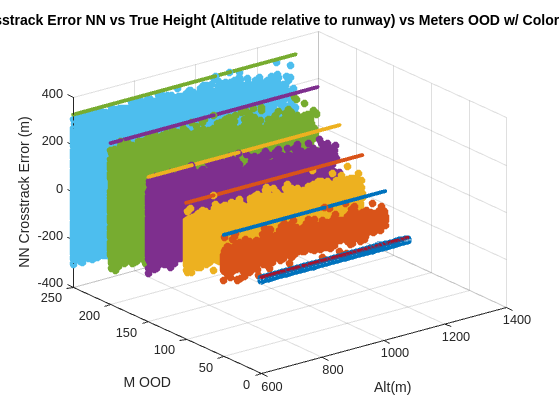


%New Plot- just to visualize cutoff and ensure reasonable 
scatter3(h50thresh, zerothresh', error_NN_y_50_t);
hold on; 
scatter3(h100thresh, fiftythresh', error_NN_y_100_t,"filled");
scatter3(h150thresh, hundredthresh', error_NN_y_150_t,"filled");
scatter3(h200thresh, hundfifthresh', error_NN_y_200_t,"filled");
scatter3(h250thresh, twohunthresh', error_NN_y_250_t,	"filled");
scatter3(h300thresh, twohunfifthresh', error_NN_y_300_t,"filled");
title('Crosstrack Error NN vs True Height (Altitude relative to runway) vs Meters OOD w/ Color Thresh');
xlabel('Alt(m)');
ylabel('M OOD');
zlabel('NN Crosstrack Error (m)');

plot3(h50thresh, zerothresh', repelem(max50, length(h50thresh)), 'LineWidth',3); 
plot3(h100thresh, fiftythresh', repelem(max100, length(h100thresh)), 'LineWidth',3); 
plot3(h150thresh, hundredthresh', repelem(max150, length(h150thresh)), 'LineWidth',3); 
plot3(h200thresh, hundfifthresh', repelem(max200, length(h200thresh)), 'LineWidth',3); 
plot3(h250thresh, twohunthresh', repelem(max250, length(h250thresh)), 'LineWidth',3); 
plot3(h300thresh, twohunfifthresh', repelem(max300, length(h300thresh)),'LineWidth',3); 
hold off; 


%Now: 2D function! Again just easier (for me) to visualize 
ood = [0, 50, 100, 150, 200, 250]; 
maxes = [max50, max100, max150, max200, max250, max300]; 
scatter(ood, maxes); 
title('Crosstrack Error NN Max vs Meters OOD @600-1400m Alt');
xlabel('M OOD');
ylabel('NN Crosstrack Error Max (m)');

%Fit a function! (5th degree polynomial)
f = fit(ood', maxes', 'poly5')

f =      Linear model Poly5:
     f(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients:
       p1 =  -4.178e-09
       p2 =   2.367e-06
       p3 =  -0.0004256
       p4 =     0.02153
       p5 =       1.829
       p6 =       8.185

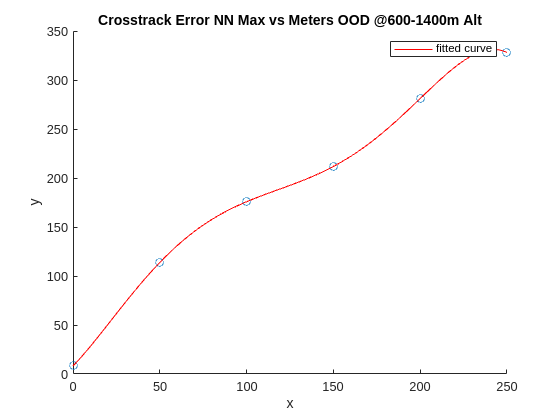

hold on; 
plot(f); 
hold off; 

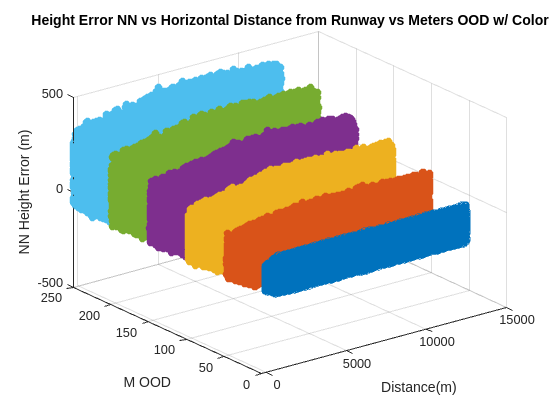


%========================================================================================

% scatter3(tab3.x, tab3.ODD_m, tab4.error_NN_h);
% %axis equal;
% title('Height Error NN vs Horizontal Distance from Runway vs Meters OOD');
% xlabel('Distance(m)');
% ylabel('M OOD');
% zlabel('NN Height Error (m)');

scatter3(x50, zero', error_NN_h_50);
hold on; 
scatter3(x100, fifty', error_NN_h_100,"filled");
scatter3(x150, hundred', error_NN_h_150,"filled");
scatter3(x200, hundfif', error_NN_h_200,"filled");
scatter3(x250, twohun', error_NN_h_250,	"filled");
scatter3(x300, twohunfif', error_NN_h_300,"filled");
title('Height Error NN vs Horizontal Distance from Runway vs Meters OOD w/ Color');
xlabel('Distance(m)');
ylabel('M OOD');
zlabel('NN Height Error (m)');
hold off; 


%Create Cutoff Threshold for data (3000 m seemed reasonable based on the
%behavior of the original graphs, but it can also be decreased or increased
%as needed) 

x50thresh = x50(x50 > 3000); 
x100thresh = x100(x100 > 3000); 
x150thresh = x150(x150 > 3000); 
x200thresh = x200(x200 > 3000); 
x250thresh = x250(x250 > 3000); 
x300thresh = x300(x300 > 3000); 

zerothresh = zero(x50 > 3000); 
fiftythresh = fifty(x100 > 3000); 
hundredthresh = hundred(x150 > 3000); 
hundfifthresh = hundfif(x200 > 3000); 
twohunthresh = twohun(x250 > 3000); 
twohunfifthresh = twohunfif(x300 > 3000); 

error_NN_h_50_t= error_NN_h_50(x50 > 3000); 
error_NN_h_100_t = error_NN_h_100(x100 > 3000); 
error_NN_h_150_t = error_NN_h_150(x150 > 3000); 
error_NN_h_200_t = error_NN_h_200(x200 > 3000); 
error_NN_h_250_t = error_NN_h_250(x250 > 3000); 
error_NN_h_300_t = error_NN_h_300(x300 > 3000); 

%Take the maxes of each error at x OOD- will be simpler mathematically than fitting a
%function to each and trying to build a new function off that 

max50 = max(max(error_NN_h_50_t), abs(min(error_NN_h_50_t)))

max50 = 102.6556

max100 = max(max(error_NN_h_100_t), abs(min(error_NN_h_100_t)))

max100 = 203.5186

max150 = max(max(error_NN_h_150_t), abs(min(error_NN_h_150_t)))

max150 = 275.6551

max200 = max(max(error_NN_h_200_t), abs(min(error_NN_h_200_t)))

max200 = 338.8168

max250 = max(max(error_NN_h_250_t), abs(min(error_NN_h_250_t)))

max250 = 375.3424

max300 = max(max(error_NN_h_300_t), abs(min(error_NN_h_300_t)))

max300 = 429.9205

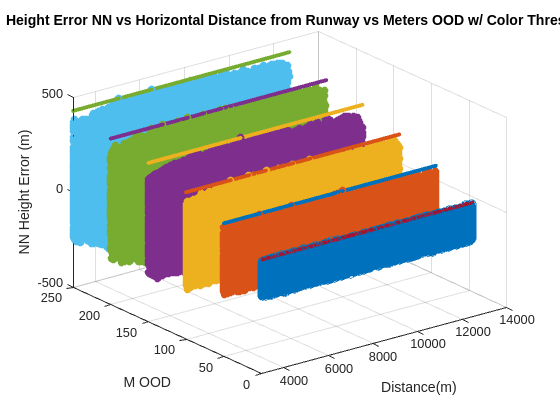


%New Plot- just to visualize cutoff and ensure reasonable 
scatter3(x50thresh, zerothresh', error_NN_h_50_t);
hold on; 
scatter3(x100thresh, fiftythresh', error_NN_h_100_t,"filled");
scatter3(x150thresh, hundredthresh', error_NN_h_150_t,"filled");
scatter3(x200thresh, hundfifthresh', error_NN_h_200_t,"filled");
scatter3(x250thresh, twohunthresh', error_NN_h_250_t,	"filled");
scatter3(x300thresh, twohunfifthresh', error_NN_h_300_t,"filled");
title('Height Error NN vs Horizontal Distance from Runway vs Meters OOD w/ Color Thresh');
xlabel('Distance(m)');
ylabel('M OOD');
zlabel('NN Height Error (m)');

plot3(x50thresh, zerothresh', repelem(max50, length(x50thresh)), 'LineWidth',3); 
plot3(x100thresh, fiftythresh', repelem(max100, length(x100thresh)), 'LineWidth',3); 
plot3(x150thresh, hundredthresh', repelem(max150, length(x150thresh)), 'LineWidth',3); 
plot3(x200thresh, hundfifthresh', repelem(max200, length(x200thresh)), 'LineWidth',3); 
plot3(x250thresh, twohunthresh', repelem(max250, length(x250thresh)), 'LineWidth',3); 
plot3(x300thresh, twohunfifthresh', repelem(max300, length(x300thresh)),'LineWidth',3); 
hold off; 


%Now: 2D function! Again just easier (for me) to visualize 
ood = [0, 50, 100, 150, 200, 250]; 
maxes = [max50, max100, max150, max200, max250, max300]; 
scatter(ood, maxes); 
title('Height Error NN Max vs Meters OOD @3000-14000m Dist');
xlabel('M OOD');
ylabel('NN Height Error Max (m)');

%Fit a function! (5th degree polynomial)
f = fit(ood', maxes', 'poly5')

f =      Linear model Poly5:
     f(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients:
       p1 =    2.66e-09
       p2 =   -1.58e-06
       p3 =   0.0003339
       p4 =    -0.03318
       p5 =       3.022
       p6 =       102.7

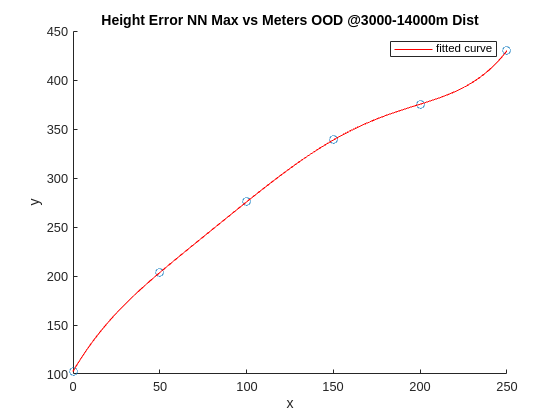

hold on; 
plot(f); 
hold off; 

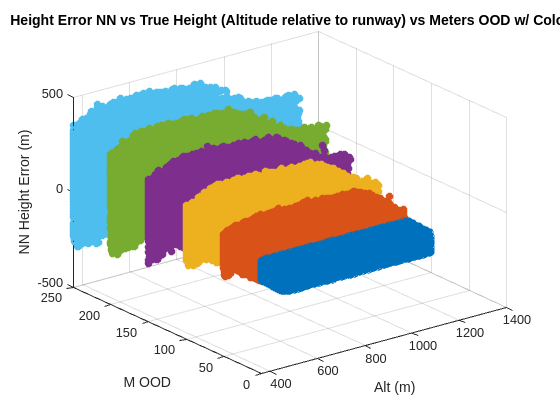


%========================================================================================

% scatter3(tab4.h, tab4.ODD_m, tab4.error_NN_h);
% %axis equal;
% title('Height Error NN vs True Height (Altitude relative to runway) vs Meters OOD');
% xlabel('Alt (m)');
% ylabel('M OOD');
% zlabel('NN Height Error (m)');

scatter3(h50, zero', error_NN_h_50);
hold on; 
scatter3(h100, fifty', error_NN_h_100,"filled");
scatter3(h150, hundred', error_NN_h_150,"filled");
scatter3(h200, hundfif', error_NN_h_200,"filled");
scatter3(h250, twohun', error_NN_h_250,	"filled");
scatter3(h300, twohunfif', error_NN_h_300,"filled");
title('Height Error NN vs True Height (Altitude relative to runway) vs Meters OOD w/ Color');
xlabel('Alt (m)');
ylabel('M OOD');
zlabel('NN Height Error (m)');
hold off; 


%I didn't threshold this one due to how the data behaves 

%Take the maxes of each error at x OOD- will be simpler mathematically than fitting a
%function to each and trying to build a new function off that 

max50 = max(max(error_NN_h_50), abs(min(error_NN_h_50)))

max50 = 102.6556

max100 = max(max(error_NN_h_100), abs(min(error_NN_h_100)))

max100 = 203.5186

max150 = max(max(error_NN_h_150), abs(min(error_NN_h_150)))

max150 = 275.6551

max200 = max(max(error_NN_h_200), abs(min(error_NN_h_200)))

max200 = 338.8168

max250 = max(max(error_NN_h_250), abs(min(error_NN_h_250)))

max250 = 375.3424

max300 = max(max(error_NN_h_300), abs(min(error_NN_h_300)))

max300 = 429.9205

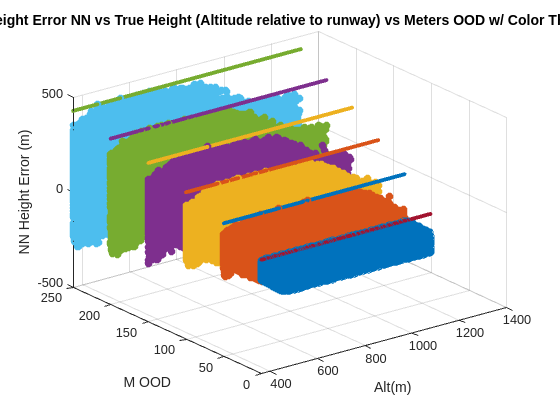


%New Plot- just to visualize cutoff and ensure reasonable 
scatter3(h50, zero', error_NN_h_50);
hold on; 
scatter3(h100, fifty', error_NN_h_100,"filled");
scatter3(h150, hundred', error_NN_h_150,"filled");
scatter3(h200, hundfif', error_NN_h_200,"filled");
scatter3(h250, twohun', error_NN_h_250,	"filled");
scatter3(h300, twohunfif', error_NN_h_300,"filled");
title('Height Error NN vs True Height (Altitude relative to runway) vs Meters OOD w/ Color Thresh');
xlabel('Alt(m)');
ylabel('M OOD');
zlabel('NN Height Error (m)');

plot3(h50, zero', repelem(max50, length(h50)), 'LineWidth',3); 
plot3(h100, fifty', repelem(max100, length(h100)), 'LineWidth',3); 
plot3(h150, hundred', repelem(max150, length(h150)), 'LineWidth',3); 
plot3(h200, hundfif', repelem(max200, length(h200)), 'LineWidth',3); 
plot3(h250, twohun', repelem(max250, length(h250)), 'LineWidth',3); 
plot3(h300, twohunfif', repelem(max300, length(h300)),'LineWidth',3); 
hold off; 


%Now: 2D function! Again just easier (for me) to visualize 
ood = [0, 50, 100, 150, 200, 250]; 
maxes = [max50, max100, max150, max200, max250, max300]; 
scatter(ood, maxes); 
title('Height Error NN Max vs Meters OOD @0-1400m Alt');
xlabel('M OOD');
ylabel('NN Height Error Max (m)');

%Fit a function! (5th degree polynomial)
f = fit(ood', maxes', 'poly5');

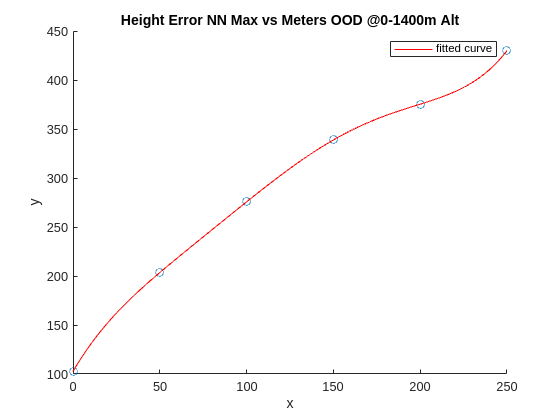

hold on; 
plot(f); 
hold off; 


%=======================================================================
%=======================================================================

%4: Write the function- transfer to written text/LaTex and connect to the
%original data generation parameters 